# Machine Learning Online Class

## =============== Part 1: Loading movie ratings dataset ================

fprintf('Loading movie ratings dataset.\n\n');

Loading movie ratings dataset.




%  Load data
load ('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies on 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', ...
        mean(Y(1, R(1, :))));

Average rating for movie 1 (Toy Story): 3.878319 / 5



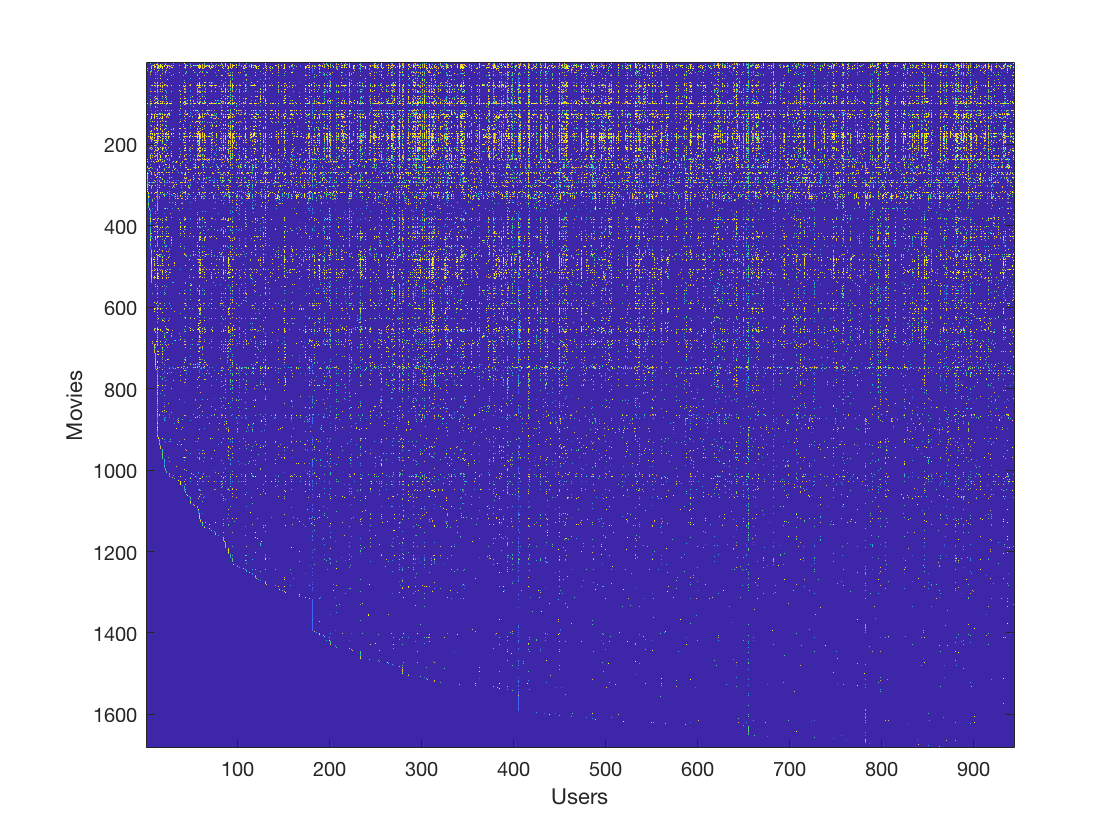


%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============ Part 2: Collaborative Filtering Cost Function ===========

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load ('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 0);
           
fprintf(['Cost at loaded parameters: %f '...
         '\n(this value should be about 22.22)\n'], J);

Cost at loaded parameters: 22.224604 
(this value should be about 22.22)



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============== Part 3: Collaborative Filtering Gradient ==============

fprintf('\nChecking Gradients (without regularization) ... \n');


Checking Gradients (without regularization) ... 



%  Check gradients by running checkNNGradients
checkCostFunction;

  -20.4233  -20.4233
   -0.1246   -0.1246
         0         0
    4.8959    4.8959
    3.6873    3.6873
    0.1608    0.1608
         0         0
   -0.8582   -0.8582
   -4.5212   -4.5212
    0.1693    0.1693
         0         0
    0.8668    0.8668
   10.4509   10.4509
   -0.8516   -0.8516
   15.3816   15.3816
         0         0
    0.2000    0.2000
   -1.1357   -1.1357
    0.0734    0.0734
   -1.6239   -1.6239
         0         0
    0.3176    0.3176
    0.2985    0.2985
   -0.0632   -0.0632
    0.5360    0.5360
         0         0
   -0.1298   -0.1298

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.32477e-12



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ========= Part 4: Collaborative Filtering Cost Regularization ========

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 1.5);
           
fprintf(['Cost at loaded parameters (lambda = 1.5): %f '...
         '\n(this value should be about 31.34)\n'], J);

Cost at loaded parameters (lambda = 1.5): 31.344056 
(this value should be about 31.34)



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ======= Part 5: Collaborative Filtering Gradient Regularization ======

%  
fprintf('\nChecking Gradients (with regularization) ... \n');


Checking Gradients (with regularization) ... 



%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

   -5.6345   -5.6345
    5.5604    5.5604
    3.0811    3.0811
    0.2357    0.2357
   -0.5756   -0.5756
   -0.0891   -0.0891
   -1.8801   -1.8801
   -1.7095   -1.7095
    8.9536    8.9536
   -1.0433   -1.0433
   -0.4709   -0.4709
   -2.9015   -2.9015
   -5.3418   -5.3418
    1.0141    1.0141
   -0.5900   -0.5900
   -0.5515   -0.5515
    5.3098    5.3098
    2.5088    2.5088
    2.2082    2.2082
   -0.1387   -0.1387
   -0.0548   -0.0548
   -1.4657   -1.4657
    0.4960    0.4960
    1.3065    1.3065
    3.4033    3.4033
   -4.5125   -4.5125
   -6.0602   -6.0602

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.56033e-12



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============== Part 6: Entering ratings for a new user ===============

movieList = loadMovieList();

%  Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;

% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(98) = 2;

% We have selected a few movies we liked / did not like and the ratings we
% gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');



New user ratings:


for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ================== Part 7: Learning Movie Ratings ====================

fprintf('\nTraining collaborative filtering...\n');


Training collaborative filtering...



%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);

initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj', 'on', 'MaxIter', 100);

% Set Regularization
lambda = 10;
theta = fmincg (@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, ...
                                num_features, lambda)), ...
                initial_parameters, options);

Iteration     1 | Cost: 3.229123e+05
Iteration     2 | Cost: 1.274475e+05
Iteration     3 | Cost: 1.039997e+05
Iteration     4 | Cost: 8.365918e+04
Iteration     5 | Cost: 6.305348e+04
Iteration     6 | Cost: 5.265006e+04
Iteration     7 | Cost: 4.754845e+04
Iteration     8 | Cost: 4.420004e+04
Iteration     9 | Cost: 4.267635e+04
Iteration    10 | Cost: 4.159553e+04
Iteration    11 | Cost: 4.094736e+04
Iteration    12 | Cost: 4.051813e+04
Iteration    13 | Cost: 4.023464e+04
Iteration    14 | Cost: 4.011176e+04
Iteration    15 | Cost: 3.988843e+04
Iteration    16 | Cost: 3.975838e+04
Iteration    17 | Cost: 3.965469e+04
Iteration    18 | Cost: 3.956621e+04
Iteration    19 | Cost: 3.946739e+04
Iteration    20 | Cost: 3.941192e+04
Iteration    21 | Cost: 3.939212e+04
Iteration    22 | Cost: 3.934312e+04
Iteration    23 | Cost: 3.931022e+04
Iteration    24 | Cost: 3.928158e+04
Iteration    25 | Cost: 3.923830e+04
Iteration    26 | Cost: 3.919760e+04
Iteration    27 | Cost: 3.918076e+04
I


% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), ...
                num_users, num_features);

fprintf('Recommender system learning completed.\n');

Recommender system learning completed.



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ================== Part 8: Recommendation for you ====================

p = X * Theta';
my_predictions = p(:,1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions, 'descend');
fprintf('\nTop recommendations for you:\n');


Top recommendations for you:


for i=1:10
    j = ix(i);
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), ...
            movieList{j});
end

Predicting rating 5.0 for movie Star Kid (1997)
Predicting rating 5.0 for movie Entertaining Angels: The Dorothy Day Story (1996)
Predicting rating 5.0 for movie Someone Else's America (1995)
Predicting rating 5.0 for movie Saint of Fort Washington, The (1993)
Predicting rating 5.0 for movie Great Day in Harlem, A (1994)
Predicting rating 5.0 for movie They Made Me a Criminal (1939)
Predicting rating 5.0 for movie Prefontaine (1997)
Predicting rating 5.0 for movie Marlene Dietrich: Shadow and Light (1996)
Predicting rating 5.0 for movie Santa with Muscles (1996)
Predicting rating 5.0 for movie Aiqing wansui (1994)



fprintf('\n\nOriginal ratings provided:\n');



Original ratings provided:


for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)
